## This exercise examines spatial variation in topographic roughness on a glacier surface using spectrograms.

`Copyright © 2019 Danica Roth <droth@mines.edu>`

`GNU General Public License`

`Canada Glacier topographic data used in this exercise was downloaded from NCALM and originally published in Telling et al., 2017 (``doi:10.3390/rs9030283).`

Clear working memory and figures, then load glacier topography data from NCALM and construct x, y and z arrays.

clear
clf

%make x, y and z arrays in units of elements
load('ncalm_CanadaGlacier.mat');
z = ncalm_CanadaGlacier.z;
% z(isnan(z))=0;
dx = ncalm_CanadaGlacier.dx;
dy = ncalm_CanadaGlacier.dy;
units = ncalm_CanadaGlacier.units;
x = [1:size(z,2)].*dx;
y = [1:size(z,1)].*dy;

Now plot the elevation data with real x-y units to visualize your glacier topography and choose a transect for your spectrogram: 

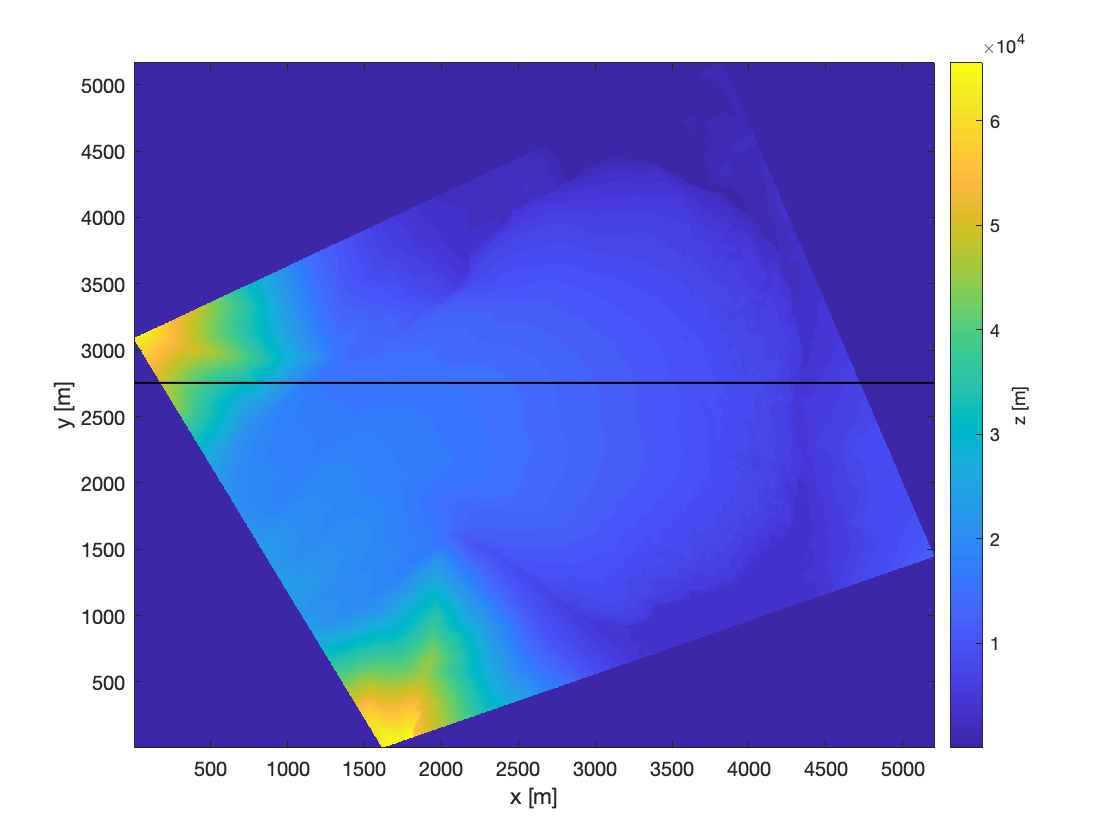

%plot elevation in xy-space
figure(1)
clf
imagesc(x,y,z);

%set origin to lower left corner and label axes
axis xy;
xlabel('x [m]');
ylabel('y [m]');

%add and label a colorbar
c = colorbar;
set(get(c,'label'),'string','z [m]','Rotation',90);

Ytransect = 2754; % Choose transect by x-value

ytrnum = Ytransect/dx; %element number for chosen transect
hold on
plot([x(1) x(end)],[y(ytrnum) y(ytrnum)],'k','linewidth',1); %plot a line showing the selected transect 

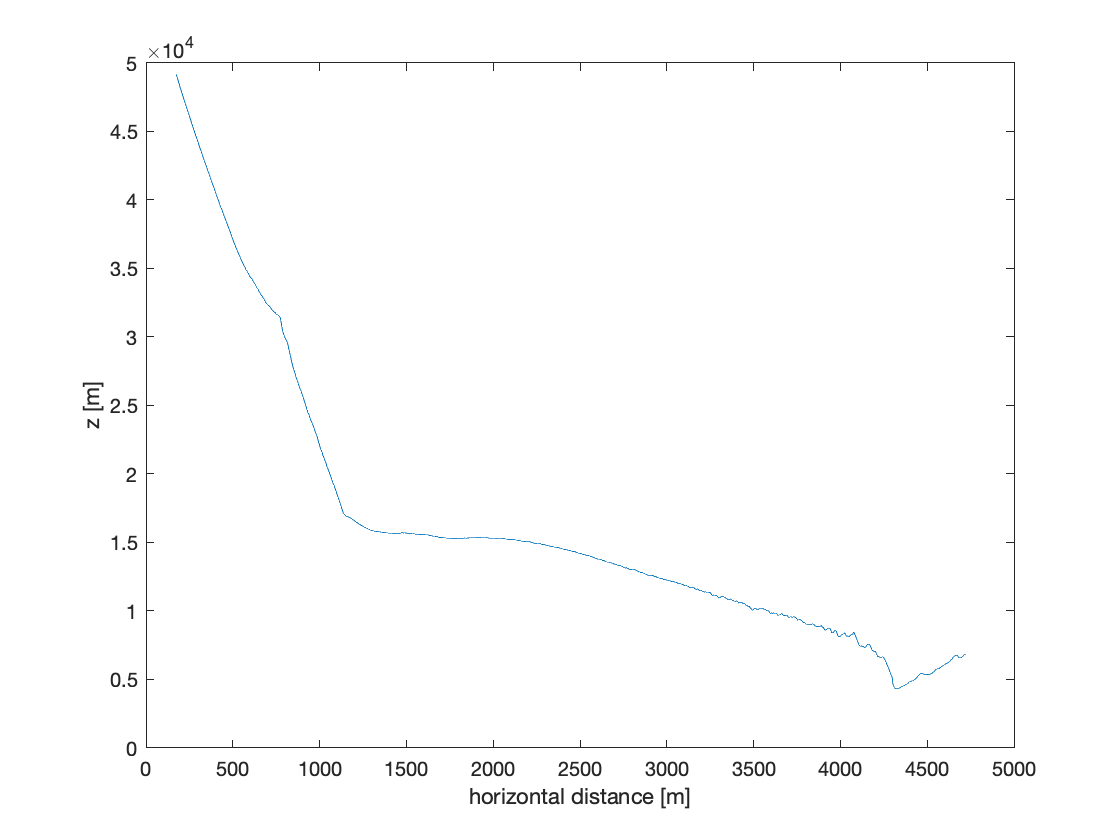

ztr = z(ytrnum,:); 

%Plot the topographic cross section of the transect
figure(2)
plot(x,ztr);
xlabel('horizontal distance [m]')
ylabel('z [m]')

## Spectrograms!

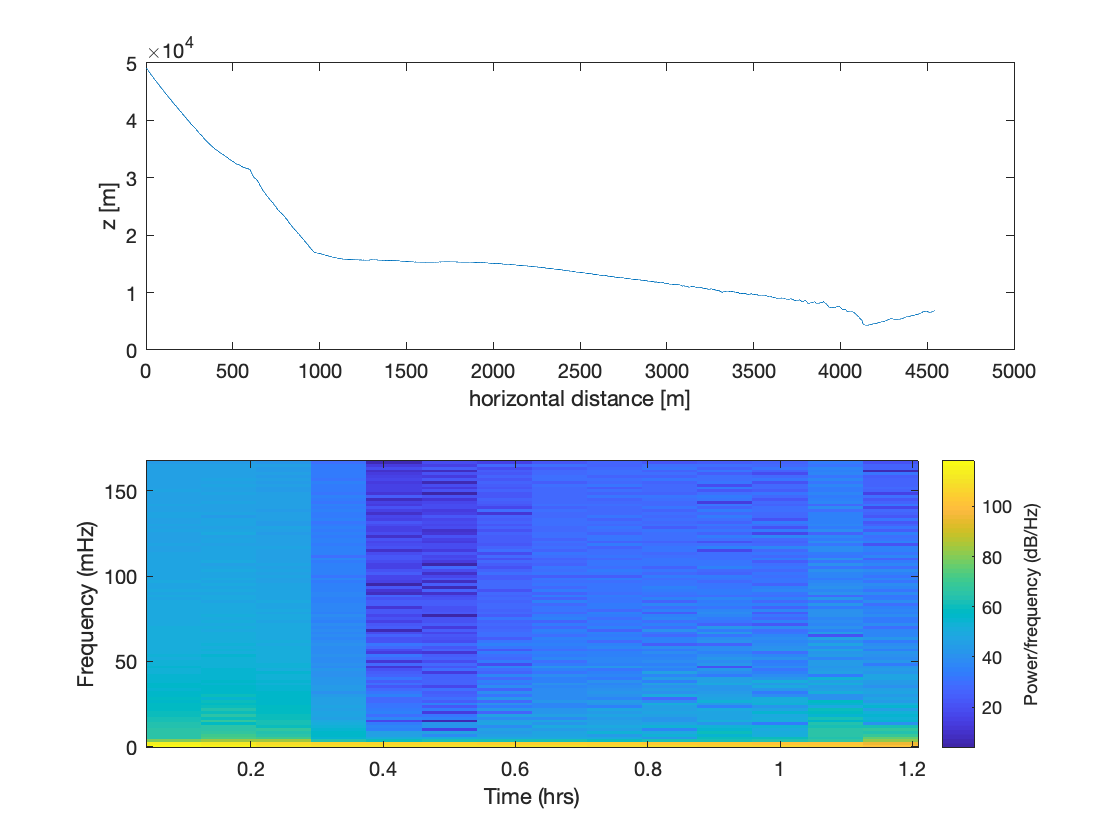

% Identify the spatial sampling frequency
fs = 1/dx; %units of samples/meter
  
window = 200; % window size in points
poverlap = 50; % percent overlap of windows
poverlap = poverlap/100;

figure(3)
clf
subplot(2,1,1)
plot(x(~isnan(ztr))-min(x(~isnan(ztr))),ztr(~isnan(ztr)));
xlabel('horizontal distance [m]')
ylabel('z [m]')
xlimits=get(gca,'xlim');

s2 = subplot(2,1,2); %create subplot with axis handle 's2' (we'll see why below)
spectrogram(ztr(~isnan(ztr)),window,window*poverlap,window,fs,'yaxis');

You may notice that the axis labels on the spectrogram above are wrong--this is because Matlab's built-in spectrogram function has a few knobs we aren't allowed to tweak, such as the units of input sample frequency (it assumes seconds or Hertz). We can get around this by using spectrogram with no output to plot, then running it again with outputs and being clever with plot axis and object handles.

Note that we set the subplot axis handle as s2 above. This allows us to call the subplot axis object, as well as its "children"--the graphics objects plotted on it. In this case, the axis object has only one child, which is the spectrogram image object. 

Try calling the axis object and clicking on "Show all properties" to get a list of all fields (these will output in the command line):

s2

s2 =   Axes with properties:

             XLim: [0.0417 1.2083]
             YLim: [-0.8333 167.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.6895 0.3412]
            Units: 'normalized'

  Show all properties


Many figure and graphics related objects store fields just like structures, which you may recall using to access our data at the very beginning of this exercise. We can query the "Children" field of s2 to see what it contains. Again, expand "Show all properties" to see everything.

s2.Children

ans =   Image with properties:

           CData: [101×14 double]
    CDataMapping: 'scaled'

  Show all properties


The Xdata and Ydata fields are the ones we're after. Spectrogram automatically rescales your data to the most "convenient" units assuming you're actually giving it time-series data in seconds. We can change these back to our true spectrogram output values by using the set function and manually changing the axis limits (note that these are two different things!):

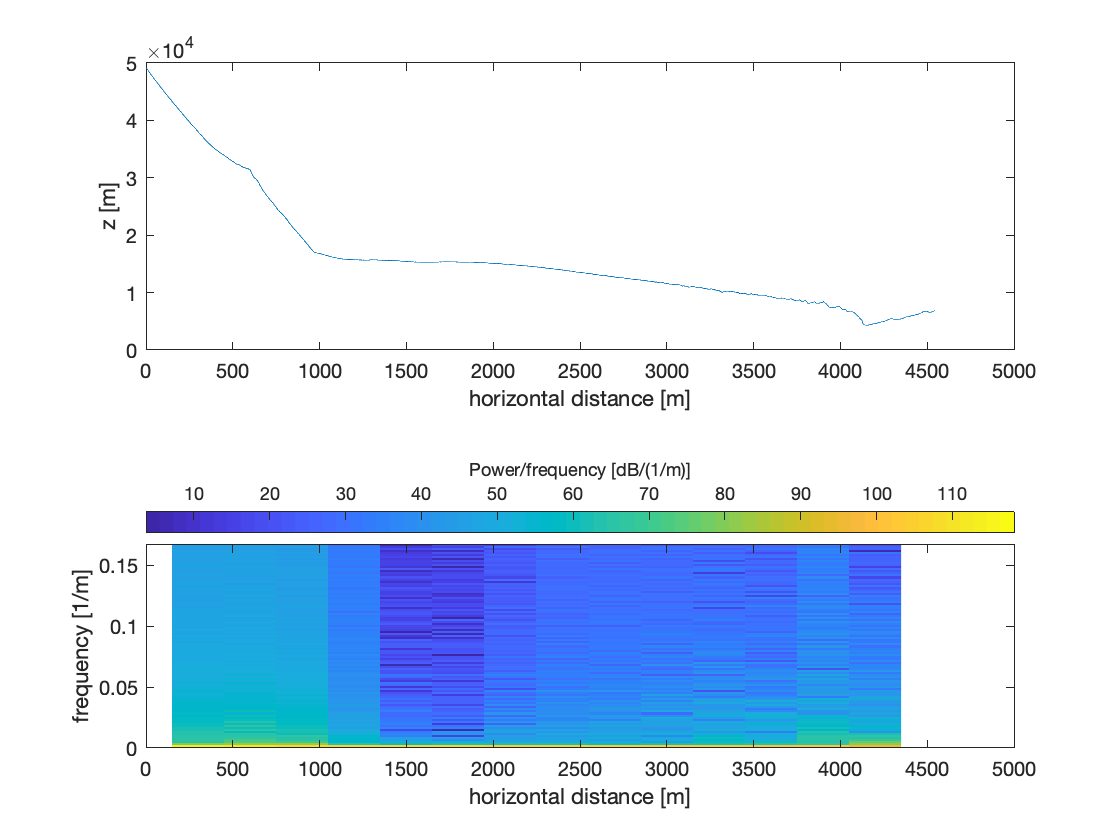

% Output short-time fourier transform (S), frequency (F), position (X), and PSD (P) arrays from spectrogram function
[S,F,X,P] = spectrogram(ztr(~isnan(ztr)),window,window*poverlap,window,fs); %note this will not plot

figure(3) %go back to our last figure

set(s2.Children,'Xdata',X); %call the child of the current axes and change data used to plot x-axis to X from spectrogram output
xlim(xlimits); %change x-axis limits to actually see our new, more accurate values
xlabel('horizontal distance [m]') %change the axis label to match our updates

set(s2.Children,'Ydata',F); %change y-axis to frequency output
ylim([min(F) max(F)]);
ylabel('frequency [1/m]')

colorbar off; %get rid of old colorbar (this may not be necessary outside of Live Scripts)
c = colorbar; %call a new colorbar and assign it a handle of 'c'
set(c,'location','northoutside') %set the colorbar location
set(get(c,'label'),'string','Power/frequency [dB/(1/m)]'); %update the units on the PSD